%根据Monte Carlo方法随机生成n个单元位置，
%计算邻接矩阵AM对应结构生成的化学概率(重要性采样方法)
%协方差矩阵+高斯分布
clc;
clear all;

n=5;
count=1e7;

%AM为考察互锁结构的邻接矩阵 
AM=ones(n)-eye(n)

AM =      0     1     1     1     1
     1     0     1     1     1
     1     1     0     1     1
     1     1     1     0     1
     1     1     1     1     0



%对于蒙特卡洛的结果进行多次重复（trial）
MC_result=[];

for l=n:0.1:n+1
    L=(n-1)*l;    
    MC_result_l=[]; %特定l下MC计算出的概率结果

for trial=1:5 %计算5此MC结果，取平均
    count1=0;
    count2=0;    
    n_mer=0;
    config=0;
    
    %尝试通过重要性采样的方法提高蒙特卡洛方法的精度
    miu = zeros(1, n-1); % 均值向量（初始化为0）
    lambda = 1; % 相关性衰减系数
    Sigma = buildCovarianceMatrix(n-1, L, lambda); % 协方差矩阵
    rng('default')  % For reproducibility

    %生成样本
    samples = mvnrnd(miu, Sigma, count); % 从多维高斯分布采样
    samples = max(min(samples, L), -L); % 约束在[-L, L]内
     
    X=samples; %第i列表示xi
    
    for i=1:count
        
        R=[0 X(i,:)]; %提取一组[x1,x2,x3,...]坐标
        start=sort(R);
        signal=1;
         
        %计算采样权重samplingweight，对应
        samplingweight=mvnpdf(X(i,:),miu,Sigma);
    
        %判断随机排列的n个单体是否生成n聚互锁结构(如是,signal=1)
        for i=2:size(start,2)
            if start(i)<=start(i-1)+l
                signal=signal*1;
            else
                signal=signal*0;
                break
            end
        end
    
        %判断随机生成的n聚结构是否满足AM的链接结构    
        if signal==1 
    
            %每次采样的贡献为概率密度权重除以采样权重
            n_mer=n_mer+Ptotal(R,l)/samplingweight; 
            count1=count1+1;
    
            if cat_config(AM,start,l)==1
                config=config+Ptotal(R,l)/samplingweight;
                count2=count2+1;
            end
    
        end 
        
    end
    
    n_mer;
    config;
    
    probability=config/n_mer %生成AM互锁结构的化学概率
    efficiency1=count1/count %蒙特卡洛方法有效计算的占比
    MC_result_l=[MC_result_l;probability];
end
MC_result=[MC_result MC_result_l];
end

probability = 4.7982e-09

efficiency1 = 0.3707

probability = 4.7982e-09

efficiency1 = 0.3707

probability = 4.7982e-09

efficiency1 = 0.3707

probability = 4.7982e-09

efficiency1 = 0.3707

probability = 4.7982e-09

efficiency1 = 0.3707

probability = 3.6045e-06

efficiency1 = 0.3707

probability = 3.6045e-06

efficiency1 = 0.3707

probability = 3.6045e-06

efficiency1 = 0.3707

probability = 3.6045e-06

efficiency1 = 0.3707

probability = 3.6045e-06

efficiency1 = 0.3707

probability = 3.5700e-04

efficiency1 = 0.3707

probability = 3.5700e-04

efficiency1 = 0.3707

probability = 3.5700e-04

efficiency1 = 0.3707

probability = 3.5700e-04

efficiency1 = 0.3707

probability = 3.5700e-04

efficiency1 = 0.3707

probability = 0.0081

efficiency1 = 0.3707

probability = 0.0081

efficiency1 = 0.3707

probability = 0.0081

efficiency1 = 0.3707

probability = 0.0081

efficiency1 = 0.3707

probability = 0.0081

efficiency1 = 0.3707

probability = 0.0604

efficiency1 = 0.3707

probability = 0.0604

efficiency1 = 0.3707

probability = 0.0604

efficiency1 = 0.3707

probability = 0.0604

efficiency1 = 0.3707

probability = 0.0604

efficiency1 = 0.3707

probability = 0.1861

efficiency1 = 0.3707

probability = 0.1861

efficiency1 = 0.3707

probability = 0.1861

efficiency1 = 0.3707

probability = 0.1861

efficiency1 = 0.3707

probability = 0.1861

efficiency1 = 0.3707

probability = 0.3196

efficiency1 = 0.3707

probability = 0.3196

efficiency1 = 0.3707

probability = 0.3196

efficiency1 = 0.3707

probability = 0.3196

efficiency1 = 0.3707

probability = 0.3196

efficiency1 = 0.3707

probability = 0.4045

efficiency1 = 0.3707

probability = 0.4045

efficiency1 = 0.3707

probability = 0.4045

efficiency1 = 0.3707

probability = 0.4045

efficiency1 = 0.3707

probability = 0.4045

efficiency1 = 0.3707

probability = 0.4452

efficiency1 = 0.3707

probability = 0.4452

efficiency1 = 0.3707

probability = 0.4452

efficiency1 = 0.3707

probability = 0.4452

efficiency1 = 0.3707

probability = 0.4452

efficiency1 = 0.3707

probability = 0.4606

efficiency1 = 0.3707

probability = 0.4606

efficiency1 = 0.3707

probability = 0.4606

efficiency1 = 0.3707

probability = 0.4606

efficiency1 = 0.3707

probability = 0.4606

efficiency1 = 0.3707

probability = 0.4627

efficiency1 = 0.3707

probability = 0.4627

efficiency1 = 0.3707

probability = 0.4627

efficiency1 = 0.3707

probability = 0.4627

efficiency1 = 0.3707

probability = 0.4627

efficiency1 = 0.3707


MC_result

MC_result =     0.0000    0.0000    0.0004    0.0081    0.0604    0.1861    0.3196    0.4045    0.4452    0.4606    0.4627
    0.0000    0.0000    0.0004    0.0081    0.0604    0.1861    0.3196    0.4045    0.4452    0.4606    0.4627
    0.0000    0.0000    0.0004    0.0081    0.0604    0.1861    0.3196    0.4045    0.4452    0.4606    0.4627
    0.0000    0.0000    0.0004    0.0081    0.0604    0.1861    0.3196    0.4045    0.4452    0.4606    0.4627
    0.0000    0.0000    0.0004    0.0081    0.0604    0.1861    0.3196    0.4045    0.4452    0.4606    0.4627


P_MC=mean(MC_result)

P_MC =     0.0000    0.0000    0.0004    0.0081    0.0604    0.1861    0.3196    0.4045    0.4452    0.4606    0.4627


var=std(MC_result)

var = 1.0e-16 *

         0         0         0         0    0.0776         0         0    0.6206         0         0         0


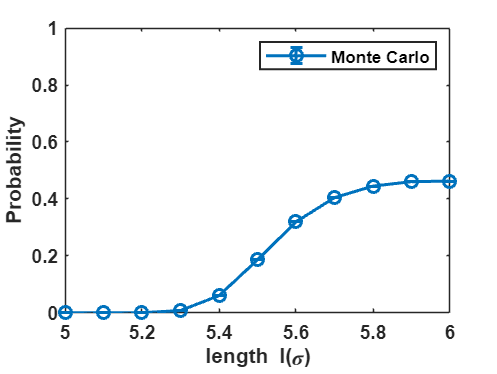



X=n:0.1:n+1;
errorbar(X,P_MC,var,'-o',LineWidth=1.5)
ylim([0 1]);

set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('length l(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('Probability','FontName','arial','FontWeight','bold');
legend( ['Monte Carlo'],'Location','northeast','FontName','arial');

function BM=border(n)
%给定阶数n，生成对映的边界矩阵BM（border matrix）
%该矩阵对映了邻接矩阵AM上三角矩阵中处于0和1边界中1的位置
   BM=zeros(n);

if n==2
   BM(:,:,end+1)=[0 1;0 0];
end

if n>2
   A=border(n-1);
   C=zeros(1,n);
   for i=1:size(A,3)
        B=[zeros(n-1,1),A(:,:,i)];
        for j=2:find(B(1,:)==1)
            C(1,j)=1;
            BM(:,:,end+1)=[C;B];
            C=zeros(1,n);
        end
   end
end
BM(:,:,1)=[];
end
%-------------------------------------------------
function AM=adj_mat(n)
%根据边界矩阵BM，写出n阶所有邻接矩阵AM
BM=border(n);
AM=zeros(n);

for i=1:size(BM,3)
    A=BM(:,:,i);
    for j=1:n-1
        for k=j+1:find(A(j,:)==1)
            A(j,k)=1;
        end
    end
    A=A+A';
    AM(:,:,end+1)=A;
end
AM(:,:,1)=[];
end



%-------------------------------------------------
function signal=cat_config(AM,seq,l)
%根据邻接矩阵AM，判断随机给出单元位置坐标的数列是否属于该构型
ran=sort(seq);

signal=1;

for i=1:size(AM,1)
    pos1=find(AM(i,:)==1);
    pos2=find(AM(i,:)==0);
    pos2(pos2==i)=[];
    for j=1:length(pos1)
        if abs(ran(i)-ran(pos1(j)))<=l
            signal=signal*1;
        else
            signal=signal*0;
            break
        end
    end

    for j=1:length(pos2)
        if abs(ran(i)-ran(pos2(j)))>l
            signal=signal*1;
        else
            signal=signal*0;
            break
        end
    end
end

signal;
%signal=1则属于该构型，反之不属于
end


%-------------------------------------------------
function a= E(r) %定义特定的势能函数E(r)
    e=4120;
    o=1;%计算的其实是o/r
    a=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
end

%-------------------------------------------------
function b=P(r) %定义相应的概率分布函数P(r)
    b=exp(-E(r)/(8.31*298));
end

%-------------------------------------------------
function f=Gauss(miu,sigma,x) %计算Gauss分布在x处的y值
    f=1/(sqrt(2*pi)*sigma)*exp(-(x-miu)^2/(2*sigma^2));
end

%-------------------------------------------------
function W=Ptotal(pos_start,l) %根据互锁单元初始位置（左盖位置）计算互锁结构的总概率密度
    density=[];
    pos_end=pos_start+l; %互锁单元末尾位置（右盖子）
    Position=sort([pos_start pos_end]);
    for i=2:length(Position)
        density=[density,P(Position(i)-Position(i-1))];
    end
    W=prod(density);
end

%-------------------------------------------------
function Sigma = buildCovarianceMatrix(n, L, lambda)
    % 构建指数衰减协方差矩阵
    Sigma = zeros(n, n);
    sigma = L / 3; % 标准差
    for i = 1:n
        for j = 1:n
            Sigma(i, j) = sigma^2 * exp(-abs(i-j)/lambda);
        end
    end
    % 正则化以确保正定性
    Sigma = Sigma + 1e-6 * eye(n);
end